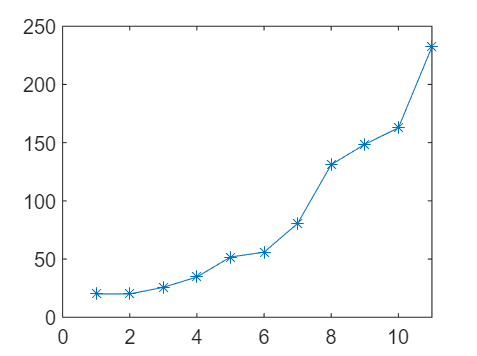

y = [20.04,20.06,25.72,34.61,51.77,55.92,80.65,131.11,148.58,162.67,232.26];
plot(y,'*-')

hold on
y=y';
n=length(y);
alpha = 0.3;
st0=mean(y(1:3));
st1(1)=alpha.*y(1)+(1-alpha).*st0;
st2(1)=alpha.*st1(1)+(1-alpha).*st0;
st3(1)=alpha.*st2(1)+(1-alpha).*st0;
for i=2:n
    st1(i)=alpha.*y(i)+(1-alpha).*st1(i-1);
    st2(i)=alpha.*st1(i)+(1-alpha).*st2(i-1);
    st3(i)=alpha.*st2(i)+(1-alpha).*st3(i-1);
end
st1

st1 =    21.3700   20.9770   22.3999   26.0629   33.7751   40.4185   52.4880   76.0746   97.8262  117.2793  151.7735


st2

st2 =    21.7690   21.5314   21.7919   23.0732   26.2838   30.5242   37.1133   48.8017   63.5091   79.6401  101.2802


st3

st3 =    21.8887   21.7815   21.7846   22.1712   23.4050   25.5408   29.0125   34.9493   43.5172   54.3541   68.4319


at=3.*st1-3.*st2+st3;
bt=alpha./(2.*(1-alpha).^2).*((6-5*alpha).*st1-(10-8*alpha).*st2+(4-3*alpha).*st3);
ct=(alpha^2)/(2*(1-alpha).^2).*(st1-2.*st2+st3);
m=1;
yhat = at+bt.*m+ct.*m^2   %最后一个是1986的预测值

yhat =    20.2300   19.5640   24.4942   34.5944   53.8901   64.5755   89.2963  142.4245  176.0860  196.2601  259.9174


yhat=[NaN,yhat]

yhat =        NaN   20.2300   19.5640   24.4942   34.5944   53.8901   64.5755   89.2963  142.4245  176.0860  196.2601  259.9174


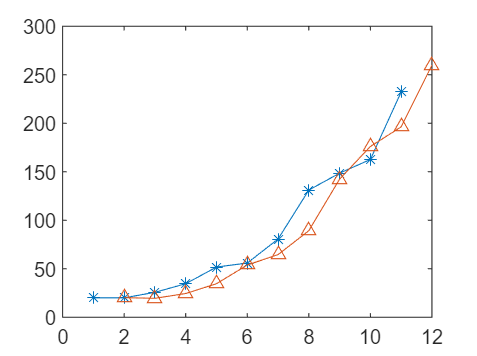

plot(yhat,'^-')